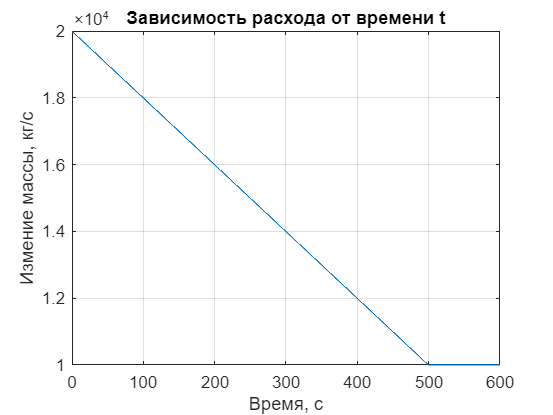

u0 = [20000 0 0 0 0 0 0 ];
options = odeset('MaxStep', 1);

[t, u] = ode45(@fcn, [0 600], u0, options);


plot(t, u(:, 1))
xlabel('Время, с');
ylabel('Измение массы, кг/с');
title('Зависимость расхода от времени t');
grid on;

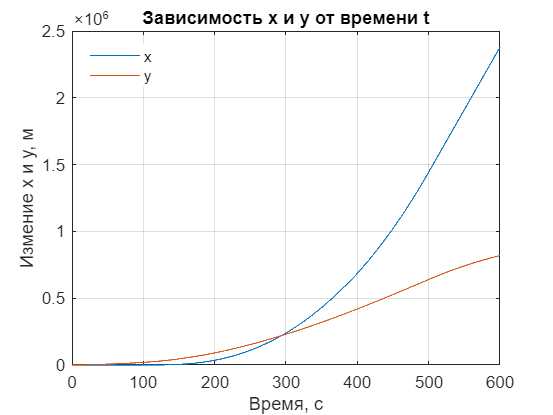


plot(t, u(:, 2))
xlabel('Время, с');
ylabel('Измение х и y, м');
title('Зависимость х и у от времени t');
grid on;
hold on;
plot(t, u(:, 3));
legend('x','y')
legend('Location','northwest')
legend('boxoff')
hold off;

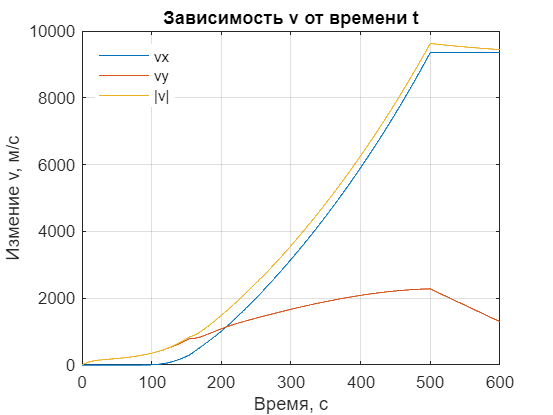


plot(t, u(:, 4))
xlabel('Время, с');
ylabel('Измение v, м/c');
title('Зависимость v от времени t');
grid on;
hold on;
plot(t, u(:, 5));
plot(t, sqrt((u(:, 4)).^2 + (u(:, 5)).^2));
legend('vx','vy','|v|')
legend('Location','northwest')
legend('boxoff')
hold off;

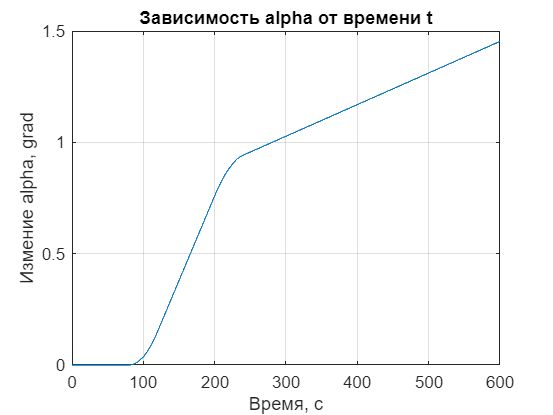



plot(t, u(:, 6))
xlabel('Время, с');
ylabel('Измение alpha, grad');
title('Зависимость alpha от времени t');
grid on;

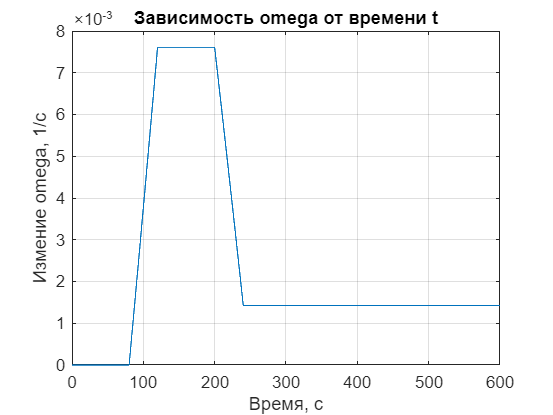


plot(t, u(:, 7))
xlabel('Время, с');
ylabel('Измение omega, 1/c');
title('Зависимость omega от времени t');
grid on;

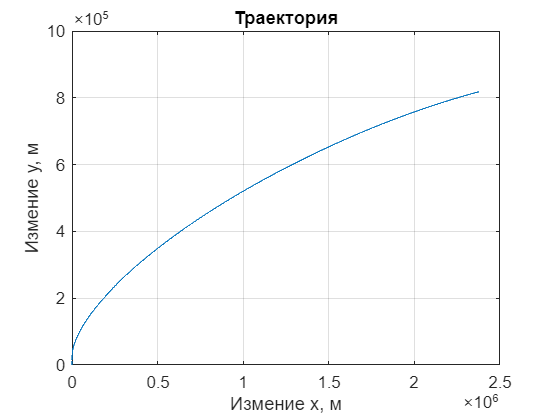


plot(u(: , 2), u(:, 3))
xlabel('Измение х, м');
ylabel('Измение y, м');
title('Траектория');
grid on;

# Функции

function dudt = fcn(t, u)

    dudt = zeros(size(u));  
    L = 70;
    m = u(1);
    y = u(3);
    vx = u(4);
    vy = u(5);
    alpha = u(6);
    omega = u(7);

    betta = cyclogramAngle(t);
    mu = massFlow(t);
    Iz = m * L^2 / 12;
    rho = airDensity(y);

    %gamma = atan(vx/vy/tan(alpha));
    %gamma = acos(sqrt(vx*vy/(vx.^2 + vy.^2))/(sqrt(sin(alpha)*cos(alpha))));
    gamma = alpha + acos(vy/sqrt(vx.^2 + vy.^2));


    F_resist = resistanceForce([vx, vy], rho, gamma); 
    
    F_grav = gravity(m);
    
    F_jet = jetForce(betta, alpha, mu);

    M = dissipationMomentum(omega, rho, L);
    
    M_jet = jetMomentum(F_jet, betta, L);

    dudt(1) = massFlow(t);
    dudt(2) = vx;
    dudt(3) = vy;
    dudt(4) = -(-F_resist(1) + F_jet(1)) / m;
    dudt(5) = -(F_resist(2) - F_grav + F_jet(2)) / m;
    dudt(6) = omega;
    dudt(7) = (M + M_jet)/Iz;
    

end

%Cила гравитации
function F_grav = gravity(m)
F_grav = -9.8*m;
end

%Плотность воздуха
function rho = airDensity(y)
    T = 300;
    R = 8.31;
    M = 0.029;
    g = 9.8;
    rho0 = 1;

    rho = rho0 * exp((-M * g * y)/(R * T));
end

%Сила сопротивления
function F = resistanceForce(v, rho, gamma)
	gamma(gamma > pi) = 2 * pi - gamma(gamma > pi);

	k = zeros(size(gamma));
	k(gamma <= pi/4) = 1;
	k(gamma > pi/4 & gamma <= 3*pi/4) = 10;
	k(gamma > 3*pi/4) = 2;

	F = v * norm(v) * k * rho * 10;

end

%Угол betta от времени
function betta = cyclogramAngle(t)

betta(t < 80) = 0;
betta(t >= 80 & t < 120) = -0.0001;
betta(t >= 120 & t < 200) = 0;
betta(t >= 200 & t < 240) = 0.00007;
betta(t >= 240) = 0;

end

%Изменение массы со временем
function mu = massFlow(t)

mu(t < 500) = -20;
mu(t >= 500) = 0;

end

%Момент силы сопротивления
function M = dissipationMomentum(omega, rho, L)

	k = 500;
	M = k * omega .^ 2 * rho * L/2;

end

%Реактивная сила
function F_jet = jetForce(betta, alpha, mu)
v_gaz = 20000;
F_jet(1) = v_gaz * mu * sin(alpha) * cos(betta);
F_jet(2) = v_gaz * mu * cos(alpha) * cos(betta);
end

%Момент реактивной силы
function M_jet = jetMomentum(F_jet, betta, L)
M_jet = -sqrt(F_jet(1).^2 + F_jet(2).^2) * sin(betta) * L / 2;
end